clear; clc; close;
caseName = "DMD_combustorDataPressure";

load(caseName + "_ContTimeEigVals.mat");

initialState = str2num(cell2mat(importdata(caseName + "_initialState",','))); % read data from file as charater array segmented by ',' put it into a matrix
b = str2num(cell2mat(importdata(caseName + "_initialAmplitudes",',')));

whos

  Name                 Size                Bytes  Class     Attributes

  b                    1x38523            616368  double    complex   
  caseName             1x1                   198  string              
  contTimeEigVals      1x38522            616352  double    complex   
  initialState         1x38523            308184  double              




initialState = initialState(1:end-1); % resize to match length of contTimeEigVals
b = b(1:end-1); % resize to match length of contTimeEigVals

psdData = [(abs(imag(contTimeEigVals(:)/2/pi))),abs(b(:)./abs(contTimeEigVals(:)))];

[max,maxIndex] = max(psdData(:,2))

max = 2.1543e+08

maxIndex = 38130

freqMax = psdData(maxIndex,1)

freqMax = 0

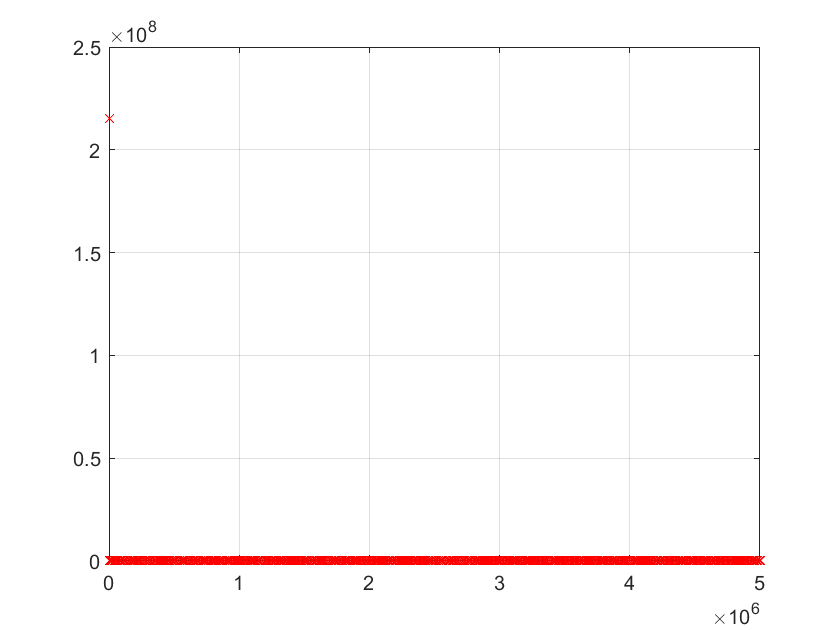


plot(psdData(:,1),psdData(:,2),'rx'); grid on;

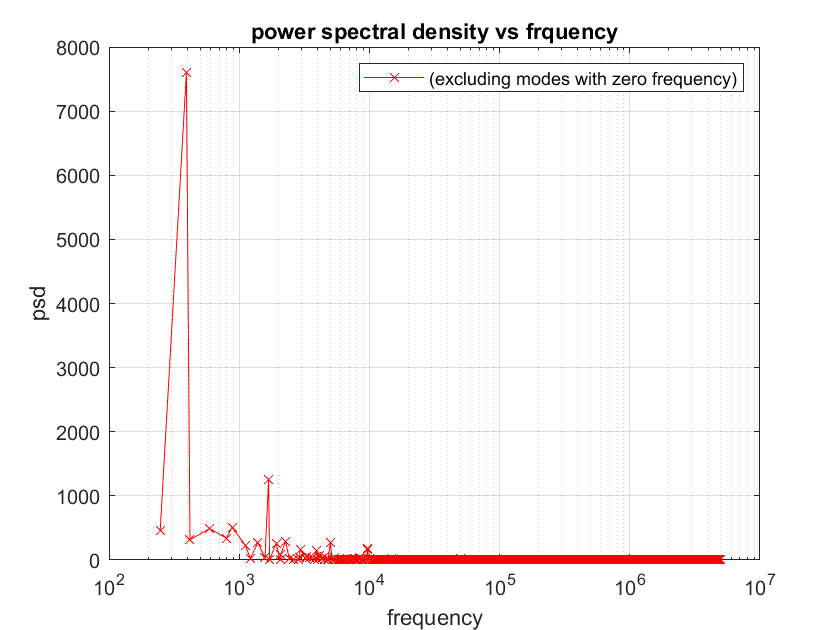

% semilogx(psdData(:,1),psdData(:,2),'rx'); grid on; %same as latter but
% without the lines that look nice

psdDataSorted =sortrows(psdData,1); % sort each column
% scatter(psdDataSorted(:,1),psdDataSorted(:,2),'rx'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency");
% plot(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency");
figure(1) = semilogx(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency"); legend("(excluding modes with zero frequency)"); % exclues modes with zero frequency
savefig("figure_"+caseName+"_psd_"+"noZeroFreqs"+".fig"); saveas(figure(1),"figure_"+caseName+"_psd_"+"noZeroFreqs"+".jpg");

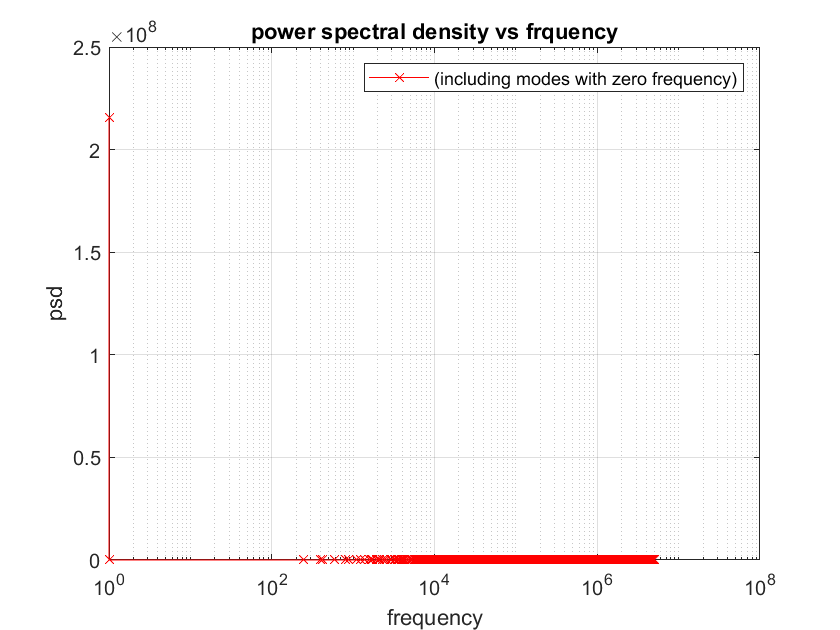

figure(2) = semilogx(psdDataSorted(:,1)+1,psdDataSorted(:,2),'r-x'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency"); legend("(including modes with zero frequency)"); % includes the modes with zero frequency by offesting frequency by one
savefig("figure_"+caseName+"_psd_"+"withZeroFreqs"+".fig"); saveas(figure(2),"figure_"+caseName+"_psd_"+"withZeroFreqs"+".jpg");


%fun but not super helpful
%loglog(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on; % does not include zero frequency
%loglog(psdDataSorted(:,1)+1,psdDataSorted(:,2),'r-x'); grid on; % includes zero frquency

%this is nice as is connects points in desending oder but is unforutnatly not exactly what i want
% psdDataSorted =sortrows(psdData,2); % sort each column
% scatter(psdDataSorted(:,1),psdDataSorted(:,2),'rx'); grid on;
% plot(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on;